# Acoustic-based machine fault detection using a wavelet scattering network paired with a recurrent neural network

The input data consists of acoustic time-series recordings from air compressors and the output is the state of the mechanical machine predicted by the LSTM-based RNN network. This standalone executable on Raspberry Pi runs the streaming classifier on the input data received from MATLAB and transfers the computed scores for each label to MATLAB on the host.

Code generation for wavelet time scattering offers significant performance improvement. See [Generate and Deploy Optimized Code for Wavelet Time Scattering on ARM Targets](docid:wavelet_ug#mw_421b92c3-5df7-4b81-a9c6-2bd31b7cfb05) for more information.

https://www.mathworks.com/help/wavelet/ug/air-compressor-fault-detection-using-wavelet-scattering.html

## **Prerequisites**

- MATLAB® Coder™

- Embedded Coder®

- [MATLAB Coder Interface for Deep Learning](https://www.mathworks.com/matlabcentral/fileexchange/68612-matlab-coder-interface-for-deep-learning-libraries#:~:text=%20When%20used%20with%20MATLAB%20Coder%2C%20MATLAB%20Coder,Cortex-A%20processors%20that%20support%20NEON%20instructions%20More%20)

- [MATLAB Support Package for Raspberry Pi Hardware](https://www.mathworks.com/hardware-support/raspberry-pi-matlab.html#:~:text=Supported%20Hardware%20%20%20%20Raspberry%20Pi%20Model,%20%20Yes%20%203%20more%20rows%20)

- Raspberry Pi hardware

- Environment variables for the compilers and libraries. For setting up the environment variables, see [Environment Variables](docid:coder_ug#mw_9ca789db-b539-4eb1-875b-677d435c0264).

For a list of supported compilers and libraries, see [Third-Party Hardware and Software](docid:coder_ug#mw_896dc1d7-0dbb-40bd-8ff1-1651e17354b4).

## Initialize

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## Load Training Data

%url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
%downloadFolder = fullfile(tempdir,'aircompressordataset');
%datasetLocation = tempdir;

%if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
%    loc = websave(downloadFolder,url);
%    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
%end

downloadFolder = fullfile('AirCompressorDataset_ALSA');
ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## Splits datastore (70% for training, 30% for testing)

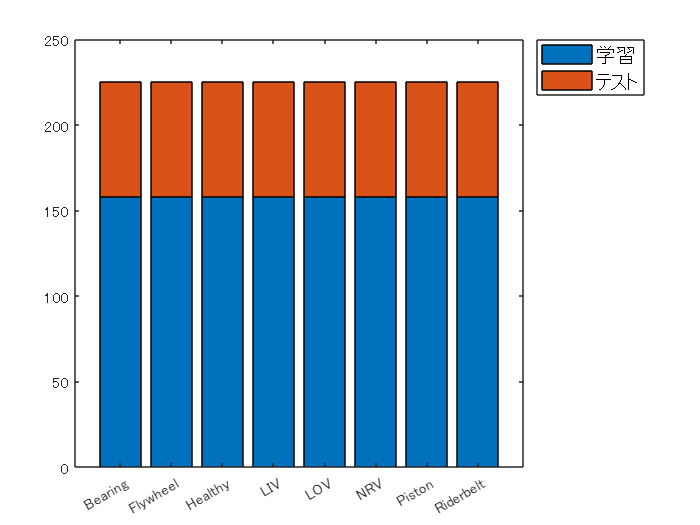

ads = shuffle(ads); %* データのシャッフル
[adsTrain,adsTest] = splitEachLabel(ads,0.7,0.3);
uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblTest.Count],'stacked');
legend(H,{'学習','テスト'},'Location','NorthEastOutside','FontSize',12)

## Visualize data

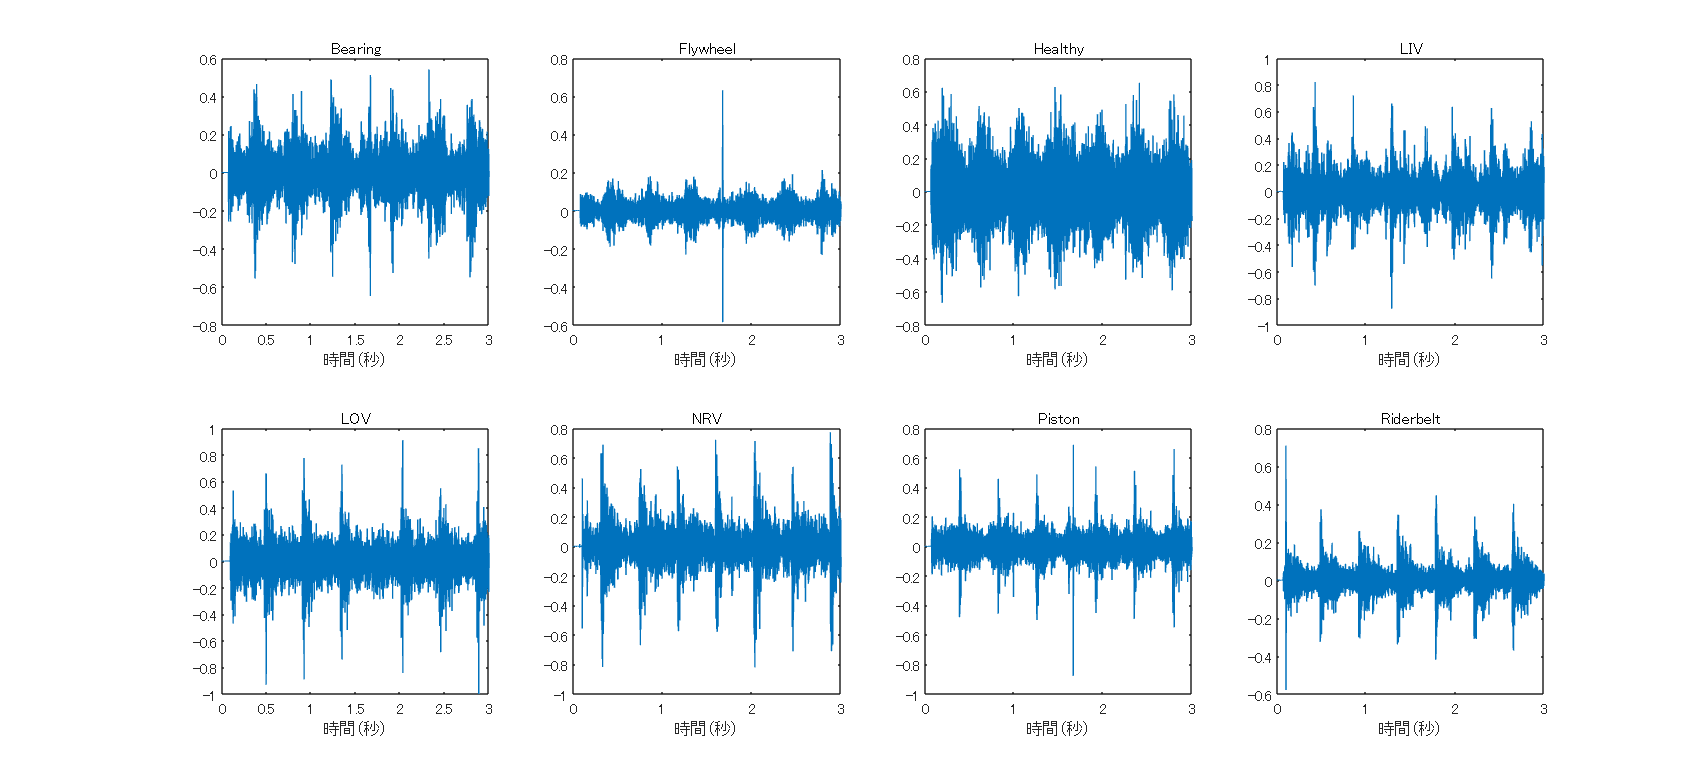

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## ハードウエアに関わる諸条件の指定

%  ハードウエア実装の際、Wavelet変換の処理でsegment faultエラーになるのを回避するため、入力信号を間引く
%  Raspberry-Piのマイク入力サンプリング周波数設定は ALSAの制約により44100Hz (or 48000Hz)
%  元データの16000Hzに比べ多すぎるので、1/3にサブサンプルして 14700Hzで使用
subsample=3; % サンプル間引き 1/3  44100Hz -> 14700
S = 44100/subsample; %サンプルレート

%　同じくWavelet変換の処理負荷軽減のため、
%  全サンプル使用せず、3秒のうち1.5秒分を使用　(2sはアウト)
% e = (nextpow2(numel(s))-1);
% N = 2^e;
span=1.5; % 採取期間 s
N = S*span; %サンプル数

%  学習には元の音声データを使用せず、スピーカーから出力し、Raspberry-Piのマイク入力を録音したものを使用
%  Raspberry-Pi上でシェルスクリプトを組んでフォルダ毎に再生&録音しているが、タイムラグが発生して
%  録音データの最初が無音状態となるため、最初のサンプルを捨てて中間のデータを学習に使用
%  この数値を変更してデータを水増し 開始タイミングの変動に強くなる？　精度は向上するが、なぜかNRVをLIVと誤判別する割合が顕著に増加
%  ofstsample = 44100*0.5; %初めの0.5秒を削除 (水増ししない場合)

% LSTMネットワークのサイズに関するパラメータ
subsample_fea=2;  % 特徴量間引き オリジナルは3だが、採取時間を半分にしたのでLSTM側に余裕ができた
LSTMreductionTgt=0.90; %LSTMパラメータ削減目標　compressNetworkUsingProjection line 256で使用

% 学習用パラメータ
batchsize = 64;
useGPU = false; %true; % Set to true to use the GPU

Wavelet Time Scattering

sn = waveletScattering('SignalLength',S*span,'SamplingFrequency', S,...
    'InvarianceScale',0.5,'Precision','single');   % was double

Prepare training sets

reset(adsTrain);
scTrain = [];
invalid_span =0.3;
tic
for ofst=invalid_span:0.2:3-span-invalid_span % 頭出しで切り捨てる秒数: データ水増し
    ofstsample=44100*ofst
    while hasdata(adsTrain)
        sc= helperbatchscatfeatures(adsTrain,sn,N,batchsize,useGPU,subsample,subsample_fea,round(ofstsample)); % subsample,subsample_fea,ofstsampleを拡張
        scTrain = cat(3,scTrain,sc);
    end
    reset(adsTrain);
end

ofstsample = 13230

ofstsample = 22050

ofstsample = 3.0870e+04

ofstsample = 3.9690e+04

ofstsample = 4.8510e+04

toc

経過時間は 187.609376 秒です。


Prepare test sets

reset(adsTest);
scTest = [];
invalid_span =0.3;
ofstsample=44100*invalid_span;
tic
while hasdata(adsTest)
   sc = helperbatchscatfeatures(adsTest,sn,N,batchsize,useGPU,subsample,subsample_fea,round(ofstsample)); % subsample,subsample_fea,ofstsampleを拡張
   scTest = cat(3,scTest,sc); 
end
toc

経過時間は 17.315870 秒です。


## Modify the training and testing scattering features to be used with the LSTM network

TrainFeatures = scTrain(2:end,:,:)

TrainFeatures = 328×6×6320 の single 配列
TrainFeatures(:,:,1) =
   -8.3581   -8.2887   -8.4689   -8.2965   -8.2520   -8.2842
   -8.4276   -8.2817   -8.5049   -8.3035   -8.2325   -8.2895
   -8.3899   -8.2621   -8.4224   -8.2759   -8.2554   -8.2841
   -8.5448   -8.4681   -8.6278   -8.5017   -8.4023   -8.4611
   -8.5027   -8.4444   -8.5663   -8.4311   -8.3637   -8.4617
   -8.7244   -8.7222   -8.8294   -8.7485   -8.6705   -8.6296
   -8.7658   -8.8092   -8.8981   -8.8522   -8.6854   -8.7123
   -8.0891   -8.1413   -8.3498   -8.3292   -8.0041   -8.3772
   -7.8301   -7.8129   -8.0237   -8.0231   -7.5317   -8.1456
   -8.3174   -8.3351   -8.5117   -8.3905   -8.2710   -8.3100
   -7.9473   -7.9463   -8.1389   -8.0871   -7.9284   -8.0646
   -7.2320   -7.0794   -7.2996   -7.1899   -6.9578   -7.1346
   -6.3954   -6.2322   -6.4717   -6.1703   -6.2269   -6.3620
   -5.4282   -5.2388   -5.5243   -5.1358   -5.1575   -5.3529
   -4.9498   -4.8303   -5.1080   -4.8338   -4.8163   -4.9027
   -5.0568   -4.8209   

TrainFeatures = squeeze(num2cell(TrainFeatures,[1 2]))

TrainFeatures = 6320×1 の cell 配列
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}
    {328×6 single}

YTrain = adsTrain.Labels;

TestFeatures = scTest(2:end,:,:);
TestFeatures = squeeze(num2cell(TestFeatures,[1 2]));
YTest = adsTest.Labels;

## Construct a simple LSTM network with 512 hidden layers

[inputSize, ~] = size(TrainFeatures{1});

numHiddenUnits = 512;
numClasses = numel(unique(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last') %* LSTM
    fullyConnectedLayer(numClasses)
    softmaxLayer];

dlnet = dlnetwork(layers)

dlnet =   dlnetwork のプロパティ:

         Layers: [4×1 nnet.cnn.layer.Layer]
    Connections: [3×2 table]
     Learnables: [5×3 table]
          State: [2×3 table]
     InputNames: {'sequenceinput'}
    OutputNames: {'softmax'}
    Initialized: 1
  summary で概要を表示します。

## Train Model

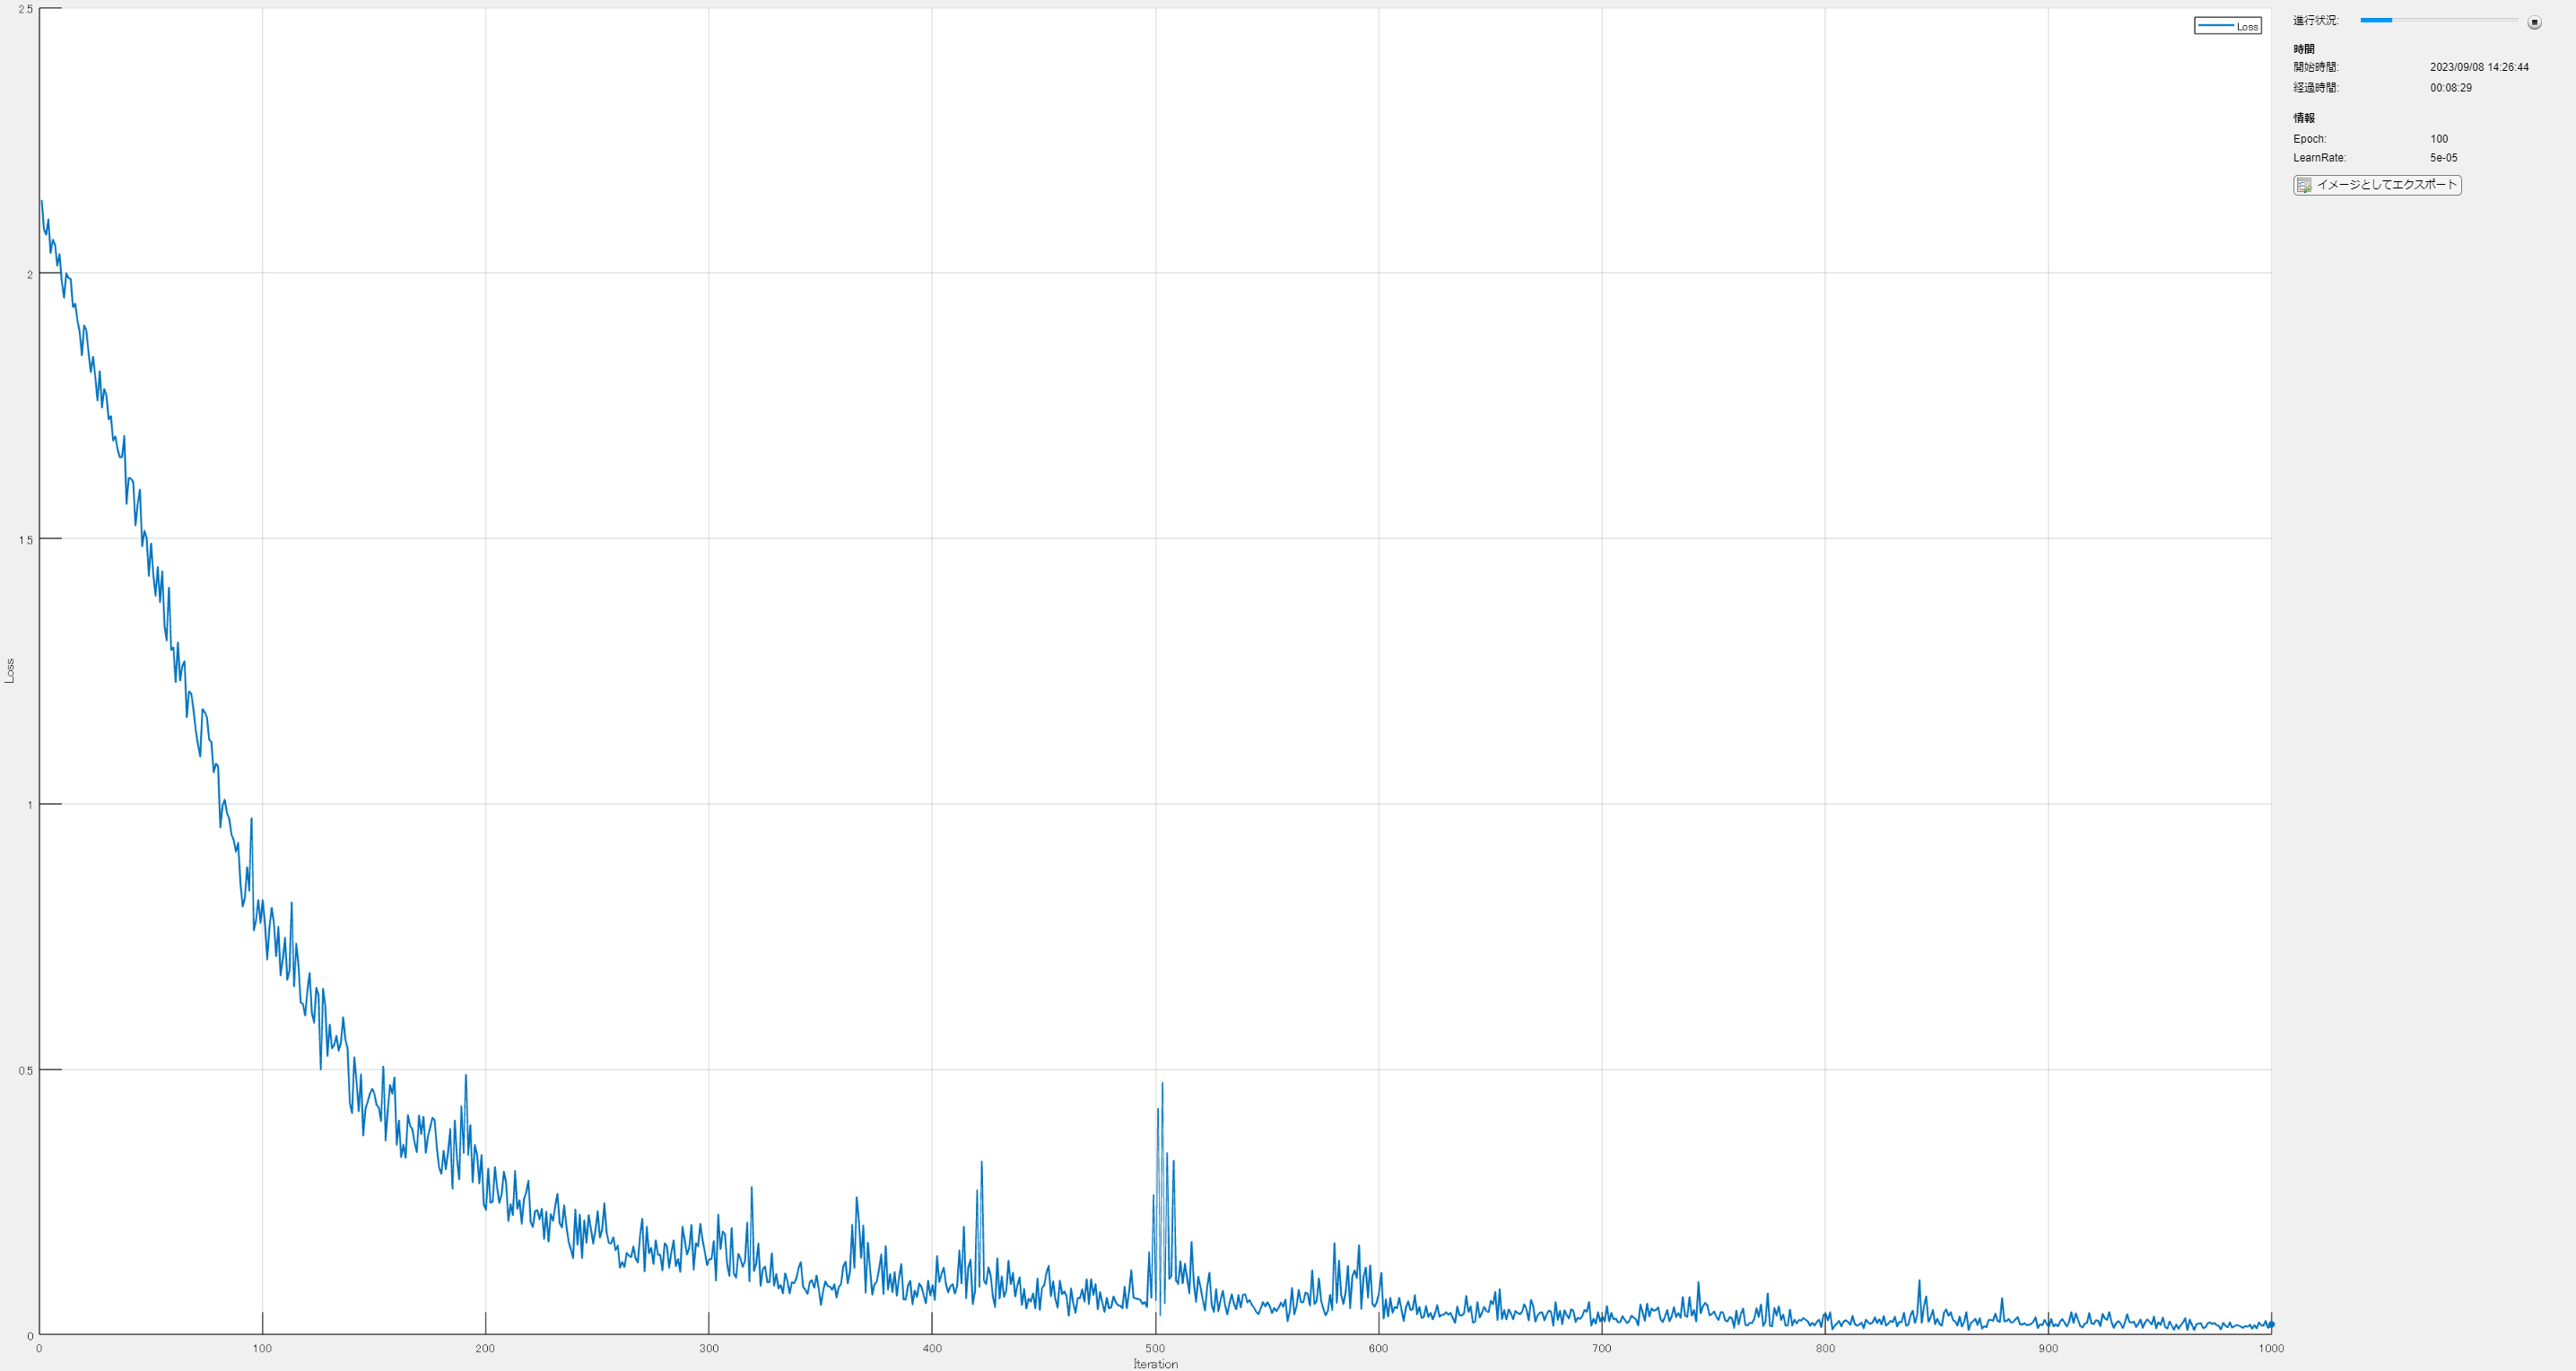

maxEpochs = 100;
miniBatchSize = 128;

initialLearnRate = 0.0001;
learnRateDecay = 0.001;

adsXTrain = arrayDatastore(TrainFeatures,OutputType="same");
adsTTrain = arrayDatastore(YTrain);
cdsTrain = combine(adsXTrain,adsTTrain);

mbq = minibatchqueue(cdsTrain,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["CTB" "CB"]);

averageGrad = [];
averageSqGrad = [];

numObservationsTrain = size(TrainFeatures,1);
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = maxEpochs * numIterationsPerEpoch;

monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info=["Epoch","LearnRate"], ...
    XLabel="Iteration");

epoch = 0;
iteration = 0;
% Loop over epochs.
while epoch < maxEpochs && ~monitor.Stop
    
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop

        iteration = iteration + 1;

        % Read mini-batch of data.
        [X,T] = next(mbq);
        
        % Evaluate the model gradients and loss using dlfeval and the
        % modelLoss function.
        [loss,gradients] = dlfeval(@modelLoss,dlnet,X,T);

        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + learnRateDecay*iteration);
        
        % Update the network parameters using the Adam optimizer.
        [dlnet,averageGrad,averageSqGrad] = adamupdate(dlnet,gradients, ...
            averageGrad,averageSqGrad,iteration,learnRate);

        % Update the training progress monitor.
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch,LearnRate=learnRate);
        monitor.Progress = 100 * iteration/numIterations;
    end
end

## Test Model

adsXTest = arrayDatastore(TestFeatures,OutputType="same");

mbqTest = minibatchqueue(adsXTest, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatchPredictors, ...
    MiniBatchFormat="CTB");

YPred = modelPredictions(dlnet,mbqTest,categories(uniqueLabels));

accuracy = mean(YPred == YTest)

accuracy = 0.9813

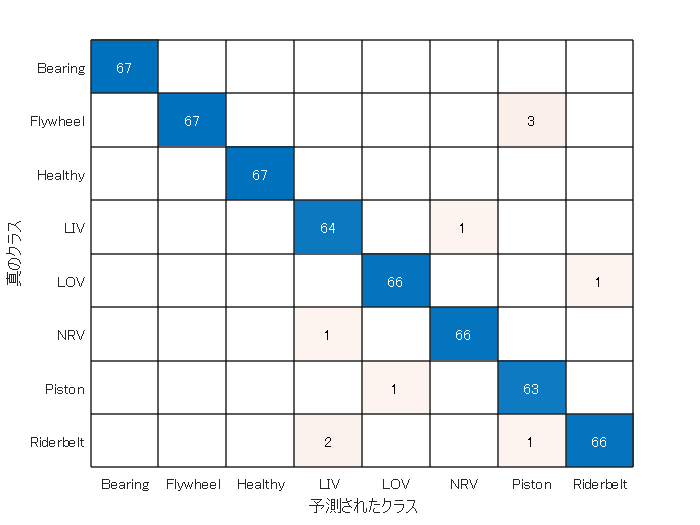

figure
confusionchart(YPred,YTest)

## Analyze Neuron Activations for Compression Using Projection

adsXTrain = arrayDatastore(TrainFeatures,OutputType="same");
mbqTrain = minibatchqueue(adsXTrain,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatchPredictors, ...
    MiniBatchFormat="CTB");

npca = neuronPCA(dlnet,mbqTrain,VerbosityLevel="steps");

Computing layer activations and covariance matrices...
Computing eigenvalues and eigenvectors...
neuronPCA analyzed 1 layers: "lstm"


npca

npca =   neuronPCA のプロパティ:

            LayerNames: "lstm"
      InputEigenvalues: {[328×1 double]}
     InputEigenvectors: {[328×328 double]}
     OutputEigenvalues: {[512×1 double]}
    OutputEigenvectors: {[512×512 double]}

## Project network

netProjected = compressNetworkUsingProjection(dlnet,npca,LearnablesReductionGoal=0.95);

Compressed network has 95.0% fewer learnable parameters.
Projected layers explain on average 89.5% of layer activation variance.


## Test Projected Network

adsTest = arrayDatastore(TestFeatures,OutputType="same");

mbqTest = minibatchqueue(adsTest, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatchPredictors, ...
    MiniBatchFormat="CTB");

YPred = modelPredictions(dlnet,mbqTest,categories(uniqueLabels));

accOriginal = mean(YPred == YTest)

accOriginal = 0.9813

Calculate the classification accuracy of the projected network

YPred = modelPredictions(netProjected,mbqTest,categories(uniqueLabels));
accProjected = mean(YPred == YTest)

accProjected = 0.2481

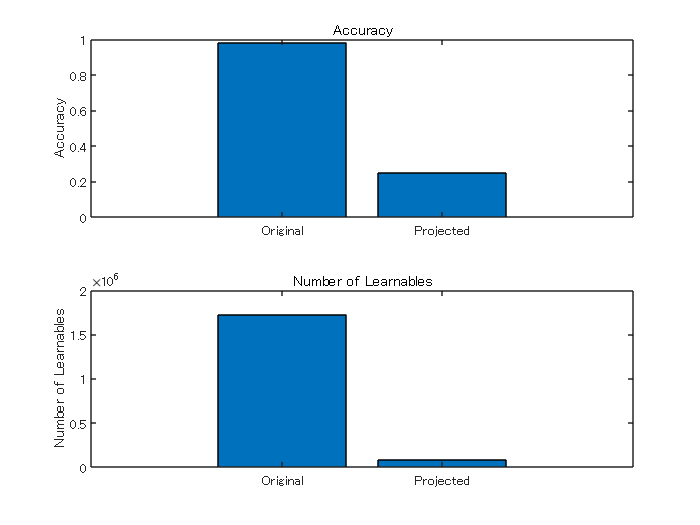

figure
tiledlayout("flow")

nexttile
bar([accOriginal accProjected])
xticklabels(["Original" "Projected"])
title("Accuracy")
ylabel("Accuracy")

nexttile
bar([numLearnables(dlnet) numLearnables(netProjected)])
xticklabels(["Original" "Projected"])
ylabel("Number of Learnables")
title("Number of Learnables")

## **Compress for Memory Requirement**

targetMemorySize = 2048*1024 % 2MB

targetMemorySize = 2097152

memorySizeOriginal = parameterMemory(dlnet)

memorySizeOriginal = 6905888

reductionGoal = 1 - (targetMemorySize/memorySizeOriginal)

reductionGoal = 0.6963

netProjected = compressNetworkUsingProjection(dlnet,npca, ...
    LearnablesReductionGoal=reductionGoal);

Compressed network has 69.8% fewer learnable parameters.
Projected layers explain on average 97.7% of layer activation variance.


memorySizeProjected = parameterMemory(netProjected)

memorySizeProjected = 2087360

reset(mbqTest)
YPred = modelPredictions(netProjected,mbqTest,categories(uniqueLabels));
accProjected = mean(YPred == YTest)

accProjected = 0.7705

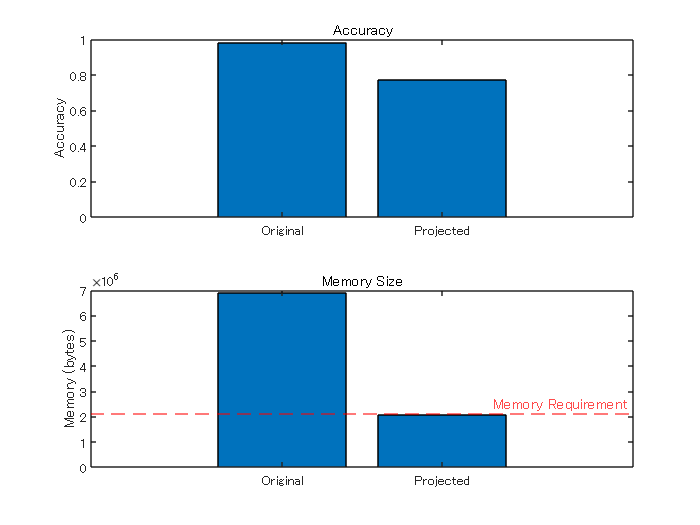

figure
tiledlayout("flow")

nexttile
bar([accOriginal accProjected])
xticklabels(["Original" "Projected"])
ylabel("Accuracy")
title("Accuracy")

nexttile
bar([memorySizeOriginal memorySizeProjected])
xticklabels(["Original" "Projected"])
yline(targetMemorySize,"r--","Memory Requirement")
ylabel("Memory (bytes)")
title("Memory Size")

## **Explore Compression Levels**

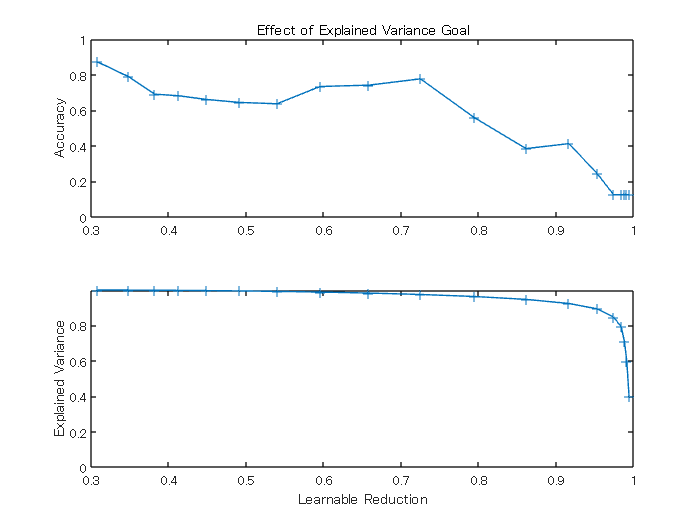

numValues = 20;
explainedVarGoal = 1 - logspace(-3,0,numValues);

for i = 1:numel(explainedVarGoal)
    varianceGoal = explainedVarGoal(i);

    [netProjected,info] = compressNetworkUsingProjection(dlnet,npca, ...
        ExplainedVarianceGoal=varianceGoal, ...
        VerbosityLevel="off");

    explainedVariance(i) = info.ExplainedVariance;
    learnablesReduction(i) = info.LearnablesReduction;

    %YPred = modelPredictions(netProjected,mbqTest,classNames);
    reset(mbqTest)
    YPred = modelPredictions(netProjected,mbqTest,categories(uniqueLabels));
    accuracy(i) = mean(YPred==YTest);
end

figure
tiledlayout("flow")

nexttile
plot(learnablesReduction,accuracy,'+-')
ylabel("Accuracy")
title("Effect of Explained Variance Goal")

nexttile
plot(learnablesReduction,explainedVariance,'+-')
ylim([0 inf])
ylabel("Explained Variance")
xlabel("Learnable Reduction")

netProjected = compressNetworkUsingProjection(dlnet,npca, ...
    LearnablesReduction=LSTMreductionTgt, ...
    VerbosityLevel="off");

reset(mbqTest)
YPred = modelPredictions(netProjected,mbqTest,categories(uniqueLabels));
accProjected = mean(YPred == YTest)

accProjected = 0.3489

## **Fine-Tune Compressed Network**

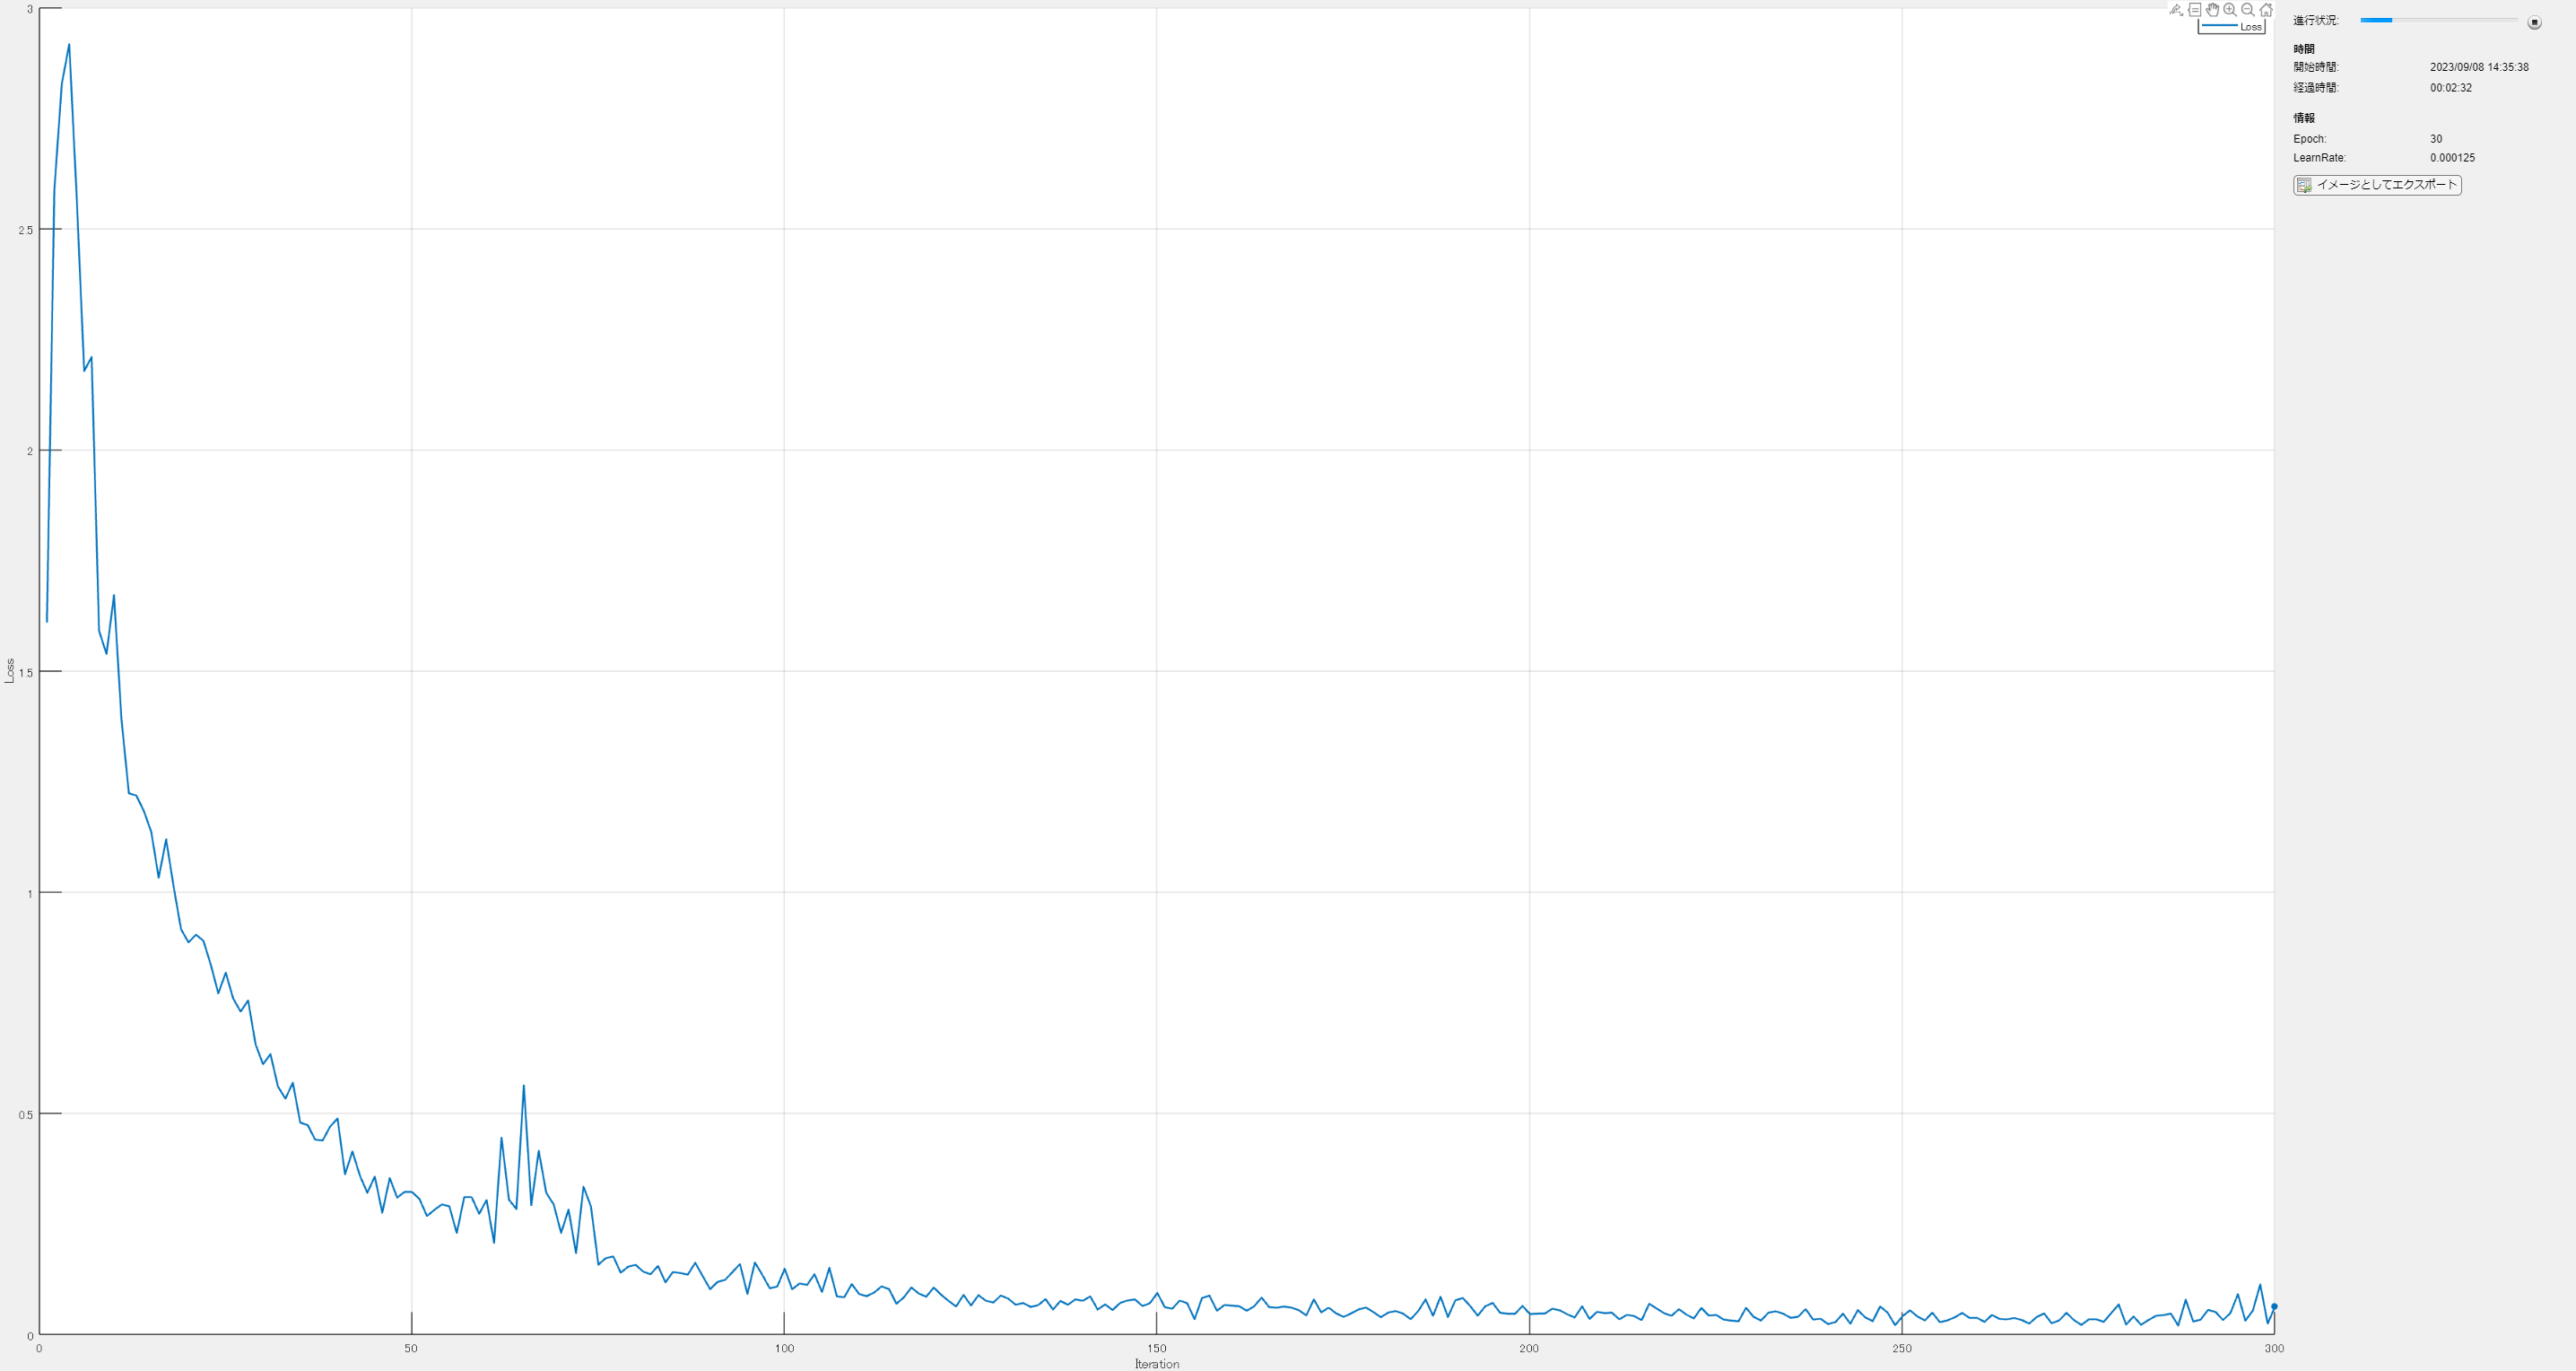

initialLearnRate = 0.0005;
learnRateDecay = 0.01;

maxEpochs = 30;
miniBatchSize = 128;

adsXTrain = arrayDatastore(TrainFeatures,OutputType="same");
adsTTrain = arrayDatastore(YTrain,IterationDimension=1);
cdsTrain = combine(adsXTrain,adsTTrain);

mbqTrain = minibatchqueue(cdsTrain,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["CTB" "CB"]);

averageGrad = [];
averageSqGrad = [];

netFineTuned = netProjected;

numObservationsTrain = size(TrainFeatures,1);
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = maxEpochs * numIterationsPerEpoch;

monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info=["Epoch","LearnRate"], ...
    XLabel="Iteration");

epoch = 0;
iteration = 0;

% Loop over epochs.
while epoch < maxEpochs && ~monitor.Stop

    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbqTrain);

    % Loop over mini-batches.
    while hasdata(mbqTrain) && ~monitor.Stop
        iteration = iteration + 1;

        % Read mini-batch of data.
        [X,T] = next(mbqTrain);

        % Evaluate the model gradients and loss using dlfeval and the
        % modelLoss function.
        [loss,gradients] = dlfeval(@modelLoss,netFineTuned,X,T);

        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + learnRateDecay*iteration);        

        % Update the network parameters using the ADAM optimizer.
        [netFineTuned,averageGrad,averageSqGrad] = adamupdate(netFineTuned,gradients, ...
            averageGrad,averageSqGrad,iteration,learnRate);

        % Update the training progress monitor.
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch,LearnRate=learnRate);
        monitor.Progress = 100 * iteration/numIterations;
    end
end

## **Test Fine-Tuned Network**

YPred = modelPredictions(netFineTuned,mbqTest,categories(uniqueLabels));
accFineTuned = mean(YPred == YTest)

accFineTuned = 0.9776

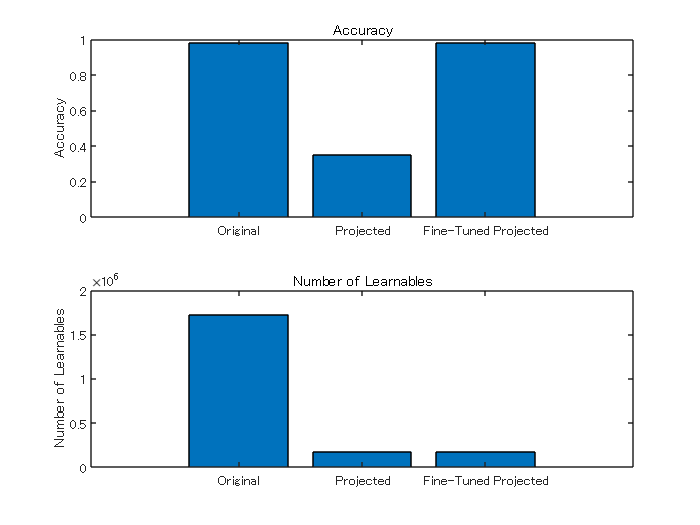

figure
tiledlayout("flow")
nexttile
bar([accOriginal accProjected accFineTuned])
xticklabels(["Original" "Projected" "Fine-Tuned Projected"])
title("Accuracy")
ylabel("Accuracy")

nexttile
bar([numLearnables(dlnet) numLearnables(netProjected) numLearnables(netFineTuned)])
xticklabels(["Original" "Projected" "Fine-Tuned Projected"])
ylabel("Number of Learnables")
title("Number of Learnables")

## Add output layer for Simulink model

dl_layers=netFineTuned.Layers

dl_layers =   次の層をもつ 4×1 の Layer 配列:

     1   'sequenceinput'   シーケンス入力   328 次元のシーケンス入力
     2   'lstm'            投影 LSTM      512 個の隠れユニットをもち、出力プロジェクターのサイズが 21、入力プロジェクターのサイズが 47 の投影 LSTM 層
     3   'fc'              全結合         8 全結合層
     4   'softmax'         ソフトマックス   ソフトマックス

netF = layerGraph(dl_layers);
%classes = categories(uniqueLabels);
classes = ["1","2","0","3","4","5","6","7"]; % Simulinkでの文字の扱いをシンプルにするため数字で出力
outputlayer=classificationLayer('Classes',classes);
netF = addLayers(netF,outputlayer);
netF = connectLayers(netF,'softmax','classoutput');
analyzeNetwork(netF)
nefProjectedFinetuned= assembleNetwork(layerGraph(netF.Layers))

nefProjectedFinetuned =   DAGNetwork のプロパティ:

         Layers: [5×1 nnet.cnn.layer.Layer]
    Connections: [4×2 table]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}

analyzeNetwork(nefProjectedFinetuned)

%save('nefProjectedFinetuned.mat','nefProjectedFinetuned')

## Supporting Functions

**Number of Learnables Function**

The `numLearnables` function returns the total number of learnables in a network.

function N = numLearnables(net)

N = 0;
for i = 1:size(net.Learnables,1)
    N = N + numel(net.Learnables.Value{i});
end

end

**Parameter Memory Function**

The `parameterMemory` function returns the size in bytes of the learnable parameters of a network, where the learnable parameters are in single precision (4 bytes per learnable).

function numBytes = parameterMemory(net)

numBytes = 4*numLearnables(net);

end

**Model Predictions Function**

The `modelPredictions` function takes a `dlnetwork` object `net`, a `minibatchqueue` of input data `mbq`, and the network classes, and computes the model predictions by iterating over all data in the `minibatchqueue` object. The function uses the `onehotdecode` function to find the predicted class with the highest score.

function Y = modelPredictions(net,mbq,classes)

Y = [];
reset(mbq)

% Loop over mini-batches.
while hasdata(mbq)
    X = next(mbq);

    % Make prediction.
    scores = predict(net,X);

    % Decode labels and append to output.
    labels = onehotdecode(scores,classes,1)';
    Y = [Y; labels];
end

end

**Model Loss Function**

The `modelLoss` function takes a `dlnetwork` object `net`, a mini-batch of input data `X` with corresponding targets `T` and returns the loss and the gradients of the loss with respect to the learnable parameters in `net`.

function [loss,gradients] = modelLoss(net,X,T)

% Forward data through network.
Y = forward(net,X);

% Calculate cross-entropy loss.
loss = crossentropy(Y,T);

% Calculate gradients of loss with respect to learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

**Preprocess Mini-Batch Function**

The `preprocessMiniBatch` function preprocesses a mini-batch of predictors and labels

function [X,T] = preprocessMiniBatch(dataX,dataT)

% Preprocess predictors.
X = preprocessMiniBatchPredictors(dataX);

% Extract label data from cell and concatenate.
T = cat(2,dataT{1:end});

% One-hot encode labels.
T = onehotencode(T,1);

end

**Mini-Batch Predictors Preprocessing Function**

The `preprocessMiniBatchPredictors` function preprocesses a mini-batch of predictors by extracting the sequence data from the input cell array and truncating them along the second dimension so that they have the same length.

function X = preprocessMiniBatchPredictors(dataX)

X = padsequences(dataX,2,Length="shortest");

end

**helperbatchscatfeatures** - This function returns the wavelet time scattering feature matrix for a given input signal. In this case, we use the natural logarithm of the wavelet scattering coefficients. The scattering feature matrix is computed on $2^{19}$ samples of a signal. The scattering features are subsampled by a factor of 6. If `useGPU` is set to `true`, the scattering transform is computed on the GPU.

function sc = helperbatchscatfeatures(ds,sn,N,batchsize,useGPU,subsample,subsample_fea,ofstsample)
% This function is only intended to support examples in the Wavelet
% Toolbox. It may be changed or removed in a future release.

% Read batch of data from audio datastore
batch = helperReadBatch(ds,N,batchsize,subsample,ofstsample);
if useGPU
    batch = gpuArray(batch);
end

% Obtain scattering features
S = sn.featureMatrix(batch,'transform','log');
gather(batch);
S = gather(S);
    
% Subsample the features
sc = S(:,1:subsample_fea:end,:);  % was  1:3:end
end

**helperReadBatch** - This function reads batches of a specified size from a datastore and returns the output in single precision. Each column of the output is a separate signal from the datastore. The output may have fewer columns than the batchsize if the datastore does not have enough records.

function batchout = helperReadBatch(ds,N,batchsize,subsample,ofstsample)
% This function is only in support of Wavelet Toolbox examples. It may
% change or be removed in a future release.
%
% batchout = readReadBatch(ds,N,batchsize) where ds is the Datastore and
%   ds is the Datastore
%   batchsize is the batchsize

kk = 1;

while(hasdata(ds)) && kk <= batchsize
    try
      tmpRead = read(ds);
    catch       % Raspberry Pi側での保存でファイル形式が壊れている場合に検出
      [~,info] = read(ds);
      disp(info);
      break;
    end

    batchout(:,kk) = cast(tmpRead(ofstsample:subsample:N*subsample+ofstsample-1),'single'); %#ok<AGROW>  % was cast(tmpRead(1:N) サンプル数多すぎるので1/subsampleに 初めのサンプルを落とす
    kk = kk+1;

end

end